clear
clc
% 读取原图
X_src=imread('LBimage2.bmp');


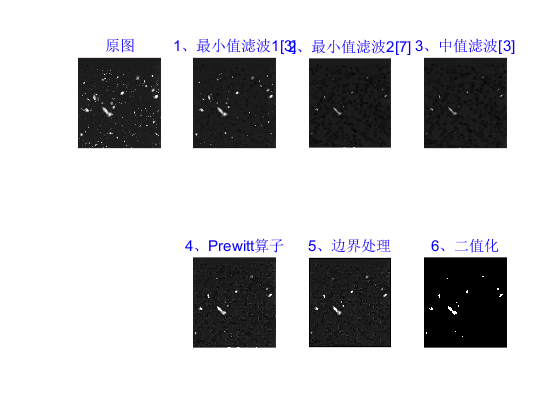

%---------------------------------------------------------------------------------------
%                                    处理方式一                                          
%---------------------------------------------------------------------------------------

%% 非线性平滑滤波器
% 序统计滤波器
% 1、最小值滤波1：检测图像最暗点
X_min1=MinFilter(double(X_src),3); 
% 2、最小值滤波1：检测图像最暗点
X_min2=MinFilter(X_min1,7); 
% 3、中值滤波：消除孤立噪声能力强，且模糊小
X_med=MedFilter(X_min2,3);

%% 非线性锐化滤波器
% 4、Prewitt算子：抑制噪声
X_prewitt=Prewitt(double(X_med));

% 5、边界处理：将边界处的像素设置为0 
X_edge = zeros(size(X_prewitt));                                % 创建同等大小的零矩阵
[height,width]=size(X_prewitt);                                 % 检索图像大小
X_edge(7:height-6,7:width-6) = X_prewitt(7:height-6,7:width-6); % 将中间部分放入零矩阵
% 6、二值化：阈值为0.5
X_bw=img2bw(X_edge,0.4); 

%% 显示结果
figure('name','滤波方式1','NumberTitle','off');
subplot(2,4,1); imshow(uint8(X_src));     title('\fontsize{11}\color{blue}原图');
subplot(2,4,2); imshow(uint8(X_min1));    title('\fontsize{11}\color{blue}1、最小值滤波1[3]');
subplot(2,4,3); imshow(uint8(X_min2));    title('\fontsize{11}\color{blue}2、最小值滤波2[7]');
subplot(2,4,4); imshow(uint8(X_med));     title('\fontsize{11}\color{blue}3、中值滤波[3]');
subplot(2,4,6); imshow(uint8(X_prewitt)); title('\fontsize{11}\color{blue}4、Prewitt算子');
subplot(2,4,7); imshow(uint8(X_edge));    title('\fontsize{11}\color{blue}5、边界处理');
subplot(2,4,8); imshow(uint8(X_bw));      title('\fontsize{11}\color{blue}6、二值化');

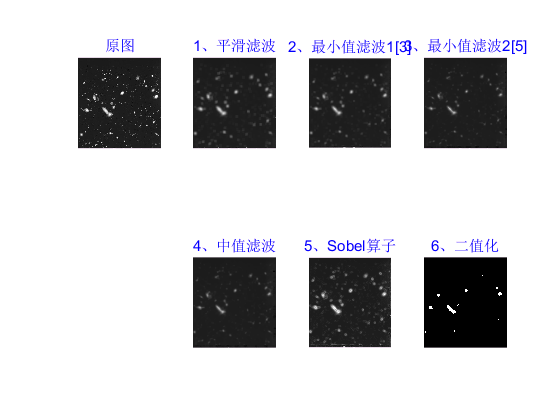

%---------------------------------------------------------------------------------------
%                                    处理方式二                                          
%---------------------------------------------------------------------------------------


%% 线性平滑滤波器
% 1、领域平均法：对图像进行平滑处理,模糊图像，以便去掉图像太小的细节,提取较大的目标
Y_ave=Average(X_src,15); 

%% 非线性平滑滤波器
% 序统计滤波器
% 2、最小值滤波1：检测图像最暗点
Y_min1=MinFilter(Y_ave,3); 
% 3、最小值滤波2：检测图像最暗点
Y_min2=MinFilter(Y_min1,5); 
% 4、中值滤波：消除孤立噪声能力强，且模糊小
Y_med=MedFilter(Y_min2,5); 

%% 非线性锐化滤波器
% 5、Sobel算子:平滑噪声
Y_sobel=Sobel(double(Y_med));

% 6、边界处理:将边界处的像素设置为0 
Y_edge = zeros(size(Y_sobel));                                    % 创建同等大小的零矩阵
[height,width]=size(Y_sobel);                                     % 检索图像大小
Y_edge(7:height-6,7:width-6) = Y_sobel(7:height-6,7:width-6);     % 将中间部分放入零矩阵
% 7、二值化:阈值为0.5
Y_bw=img2bw(Y_edge,0.5);          

%% 显示结果
figure('name','滤波方式2','NumberTitle','off');
subplot(2,4,1); imshow(uint8(X_src));   title('\fontsize{11}\color{blue}原图');
subplot(2,4,2); imshow(uint8(Y_ave));   title('\fontsize{11}\color{blue}1、平滑滤波');
subplot(2,4,3); imshow(uint8(Y_min1));  title('\fontsize{11}\color{blue}2、最小值滤波1[3]');
subplot(2,4,4); imshow(uint8(Y_min2));  title('\fontsize{11}\color{blue}3、最小值滤波2[5]');
subplot(2,4,6); imshow(uint8(Y_med));   title('\fontsize{11}\color{blue}4、中值滤波');
subplot(2,4,7); imshow(uint8(Y_sobel)); title('\fontsize{11}\color{blue}5、Sobel算子');
subplot(2,4,8); imshow(uint8(Y_bw));    title('\fontsize{11}\color{blue}6、二值化');